# Experimental Methods HW #6 Dan Lawson

## Problem 1: Least-Square Fit Regression

% Using the least-square regression analysis, determine the values of the
% exponent (gamma), constant (c), standard deviation (sig) of the original
% fit, and plot the best fit relation with the data

% P = C / V^gamma, so  P = C * V^-gamma or y = a * x^-b

clear
x = [50 30 20 15 10 5];
y = [16.6 39.7 78.5 115.5 195.3 546.1];

X = log(x);
Y = log(y);

fprintf('                                  Problem #1')

                                  Problem #1


coefs = polyfit(X,Y,1)

coefs =    -1.4991    8.7598



b = coefs(1)

b = -1.4991

a = exp(coefs(2))

a = 6.3729e+03

p = [a b];

xlin = linspace(x(1), x(end), 1000);

fit = a .* (xlin.^b);
fit2 = a .* (x.^b);

% Compute Standard Deviation and Plot

std = sqrt(sum((y - fit2).^2)/(length(x)-2))

std = 13.5923

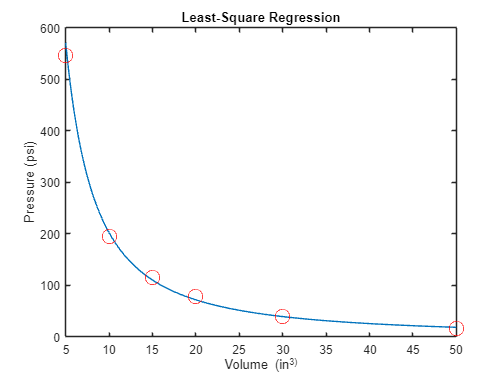


figure

plot(xlin, fit)
hold on
plot(x, y,'ro', MarkerSize=12)
xlabel('Volume (in^3)')
ylabel('Pressure (psi)')
title('Least-Square Regression')

hold off


## Problem 3: Converting an Anolog Signal

% Perform the following with the anaolog signal: E(t) = 5cos(3*pi*t)

% Using sampling time increments of 0.2, 0.5, and 0.75 seconds, plot each
% discrete series as a function of time over 50 seconds, find each Nyquist Freq

% Create time interval arrays based on the time interval for each sample

t1 = (0:0.2:50);
t2 = (0:0.5:50);
t3 = (0:0.75:50);

% Plot the signal over each time interval and display the Nyquist
% Frequencies for each of them

E1 = 5*cos(3*pi*t1);
E2 = 5*cos(3*pi*t2);
E3 = 5*cos(3*pi*t3);

figure
hold on

fprintf('                                      Problem #3')

                                      Problem #3


fsamp1 = 1 / 0.2; % The sample frequency is just 1 / (time interval)
fsamp2 = 1 / 0.5;
fsamp3 = 1 / 0.75;

Nyq1 = fsamp1 / 2 % Freq_Nyq = Freq_sample / 2

Nyq1 = 2.5000

Nyq2 = fsamp2 / 2 % Frequencies displayed in Hz

Nyq2 = 1

Nyq3 = fsamp3 / 2

Nyq3 = 0.6667

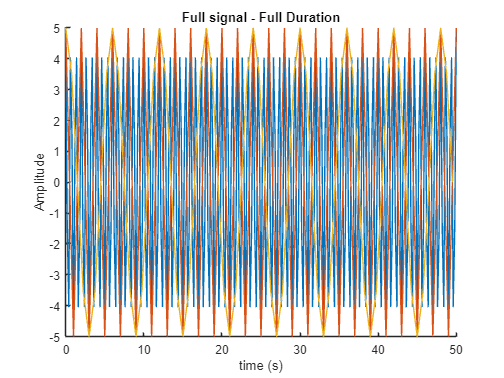


plot(t1,E1)
plot(t2,E2)
plot(t3,E3)
xlabel('time (s)')
ylabel('Amplitude')
title('Full signal - Full Duration')

hold off

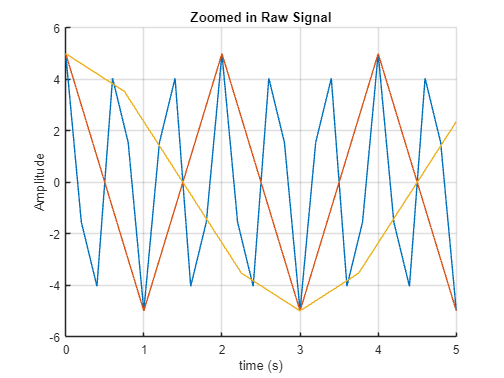


figure
hold on

plot(t1,E1)
plot(t2,E2)
plot(t3,E3)
xlabel('time (s)')
ylabel('Amplitude')
xlim([0 5])
ylim([-6 6])
title('Zoomed in Raw Signal')
grid on

hold off

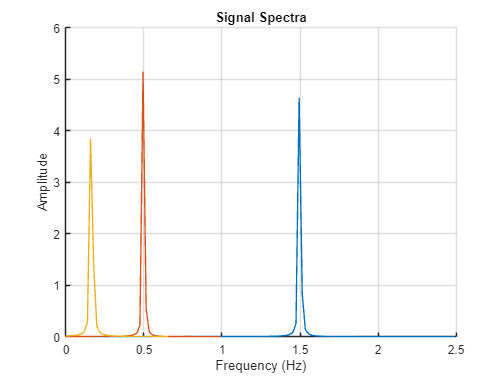


% Compute Discrete Fourier Transforms of each discretized series with fft

fourier1 = fft(E1); % take the fast fourier transform of each discretized version of the signal
fourier2 = fft(E2);
fourier3 = fft(E3);

C_k1 = fourier1 / length(fourier1); % compute the FT coefficients, C_k, where we take the fft
C_k2 = fourier2 / length(fourier2); % and divide it by N, the number of elements from the signal
C_k3 = fourier3 / length(fourier3); % or I believe, from the signal block

spectra1 = abs(C_k1).^2; % compute "the spectra",  simply |c_k| values squared
spectra2 = abs(C_k2).^2;
spectra3 = abs(C_k3).^2;

freq1 = fsamp1 * [0:length(fourier1)-1] / length(fourier1);
freq2 = fsamp2 * [0:length(fourier2)-1] / length(fourier2);
freq3 = fsamp3 * [0:length(fourier3)-1] / length(fourier3);

% Plot the "Spectra", |c_k|^2, as a function of the frequency, use
% (freq"x"<Nyq"x") logical indexing to cut off each signal at the Nyq

figure
hold on
grid on

plot(freq1(freq1<Nyq1),spectra1(freq1<Nyq1))
plot(freq2(freq2<Nyq2),spectra2(freq2<Nyq2))
plot(freq3(freq3<Nyq3),spectra3(freq3<Nyq3))
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Signal Spectra')